%here we use two voices as sample
if exist('Data/validation')%#ok
    copyfile 'Data/validation/train/B1.m4a';
    copyfile 'Data/validation/train/S1.m4a';
end

%here we add helperfunctions 
addpath(genpath(pwd));
addpath('./HelperFunctions');
warning off;  

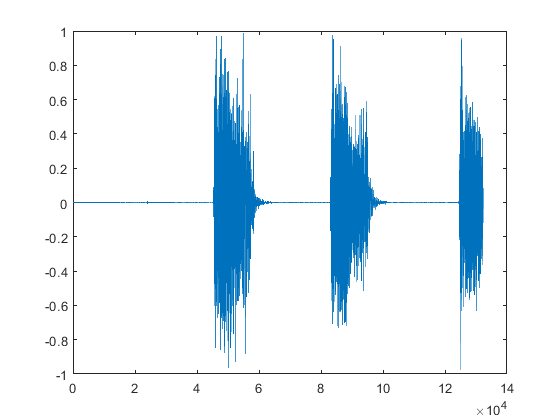

%here we play and plot cough sample
[Cough, fs] = audioread('S1.m4a');
p_cough = audioplayer(Cough, fs);
play(p_cough, [1 (get(p_cough, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(Cough(1:fs*3))

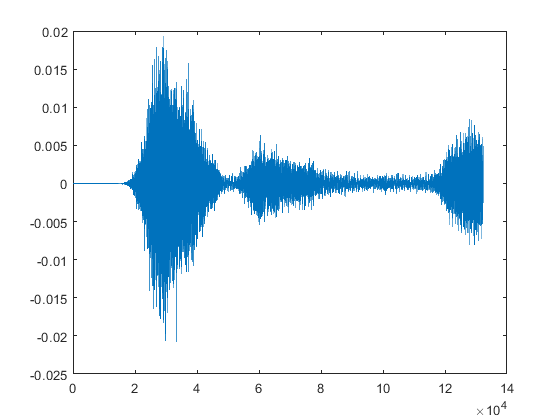

%here we play and plot breath sample
[breath, fs] = audioread('B1.m4a');
p_breath = audioplayer(breath, fs);
play(p_breath, [1 (get(p_breath, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(breath(1:fs*3))

%here we use this tool to see signals PSD and compare them
signalAnalyzer(Cough, breath)

% expecting the training data in subfolders of 'Data\validation\*'
training_fds = fileDatastore(fullfile(pwd, 'Data', 'validation', 'train'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.m4a','IncludeSubfolders',true);

%here we add our dataset
data_dir = fullfile(pwd, 'Data', 'validation');
folder_list = dir([data_dir filesep 'train*']);

reference_table = table();

for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = breth, -1 = cogh
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

Processing files from folder: train


%here we found features from dataset
runExtraction = false; % control whether to run feature extraction (will take several minutes)
   % Note: be sure to have the training data downloaded before executing
   % this section!
if runExtraction | ~isfile('FeatureTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
   % n_parts = numpartitions(training_fds, gcp);
    n_parts = 50;
    % Note: You could distribute computation across available processors by using 
    % parfor instead of "for" below, but you'll need to omit keeping track
    % of signal lengths
    for ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        
        % Extract features for the sub datastore
        [feature_win,sampleN] = extractFeatures(subds, win_len, win_overlap, reference_table);
        
        % and append that to the overall feature table we're building up
        feature_table = [feature_table; feature_win];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');

else % simply load the precomputed features
    load('FeatureTable.mat');
    disp('FeatureTable.mat loaded')
end

Part 1 done.
Part 2 done.
Part 3 done.
Part 4 done.
Part 5 done.
Part 6 done.
Part 7 done.
Part 8 done.
Part 9 done.
Part 10 done.
Part 11 done.
Part 12 done.
Part 13 done.
Part 14 done.
Part 15 done.
Part 16 done.
Part 17 done.
Part 18 done.
Part 19 done.
Part 20 done.
Part 21 done.
Part 22 done.
Part 23 done.
Part 24 done.
Part 25 done.
Part 26 done.
Part 27 done.
Part 28 done.
Part 29 done.
Part 30 done.
Part 31 done.
Part 32 done.
Part 33 done.
Part 34 done.
Part 35 done.
Part 36 done.
Part 37 done.
Part 38 done.
Part 39 done.
Part 40 done.
Part 41 done.
Part 42 done.
Part 43 done.
Part 44 done.
Part 45 done.
Part 46 done.
Part 47 done.
Part 48 done.
Part 49 done.
Part 50 done.



% Take a look at the feature table
disp(feature_table(1:5,:))

    meanValue     medianValue    standardDeviation    meanAbsoluteDeviation    quantile25     quantile75    signalIQR     sampleSkewness    sampleKurtosis    signalEntropy    MFCC1      MFCC2      MFCC3       MFCC4      MFCC5      MFCC6      MFCC7       MFCC8      MFCC9     MFCC10     MFCC11      MFCC12     MFCC13      class  
    __________    ___________    _________________    _____________________    ___________    __________    __________    ______________

%now we use features to classification
classificationLearner

% using split function defined at end of script to divide feature table
% into training and test set, holding out 20% because we need 40 for train
% and 10 for testing and all samples are 50
[training_set, test_set] = splitDataSets(feature_table,0.2);

%here we find parameters by matlab
% Assign higher cost for misclassification of cough sounds
C = [0, 10; 1, 0];        

% Create a random sub sample (to speed up training) of 1/4 of the training set
%subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
% OR train on the whole training set
subsample = 1:height(training_set);

rng(1);

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

% Step 2: train the model with hyperparameter tuning (unless you simply
% load an existing pre-trained model)

% train ensemble of decision trees (random forest)
disp("Training Ensemble classifier...")

Training Ensemble classifier...


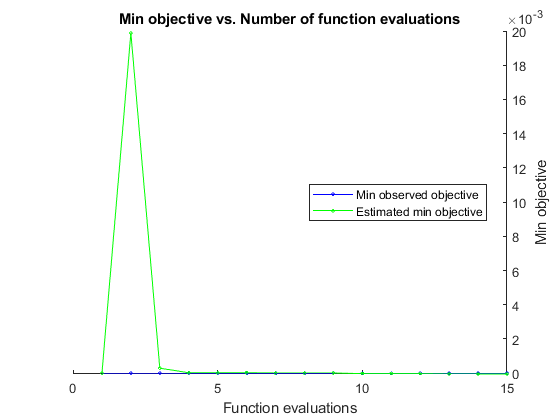

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |
|====================================================================================================================|
|    1 | Best   |           0 |      92.411 |           0 |           0 |          Bag |          421 |            - |
|    2 | Accept |         0.5 |     0.94595 |           0 |     0.01988 |     RUSBoost |          277 |    0.0028086 |
|    3 | Accept |           0 |      3.2171 |           0 |  0.00029257 |  GentleBoost |           13 |    0.0099514 |
|    4 | Accept |         0.5 |     0.93435 |           0 |  2.4999e-05 |     RUSBoost |           42 |      0.27696 |
|    5 | Accept |           0 |      5.1777 |   

trained_model =   classreg.learning.classif.ClassificationEnsemble
                       PredictorNames: {1×23 cell}
                         ResponseName: 'class'
                CategoricalPredictors: []
                           ClassNames: {'breath'  'cough'}
                       ScoreTransform: 'none'
                      NumObservations: 40
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 13
                               Method: 'GentleBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [13×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, 

    
% bayesian optimization parameters (stop after 15 iterations)
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',15);    
trained_model = fitcensemble(training_set(subsample,:),'class','Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'},...
        'HyperparameterOptimizationOptions',opts)

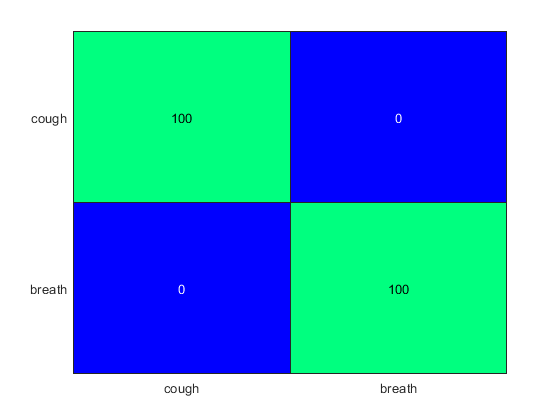


% Step 3: evaluate accuracy on held-out test set

% Predict class labels for the validation set using trained model
% NOTE: if training ensemble without optimization, need to use trained_model.Trained{idx} to predict
predicted_class = predict(trained_model, test_set);

conf_mat = confusionmat(test_set.class, predicted_class);

conf_mat_per = conf_mat*100./sum(conf_mat, 2);

% Visualize model performance in heatmap
labels = {'cough', 'breath'};
heatmap(labels, labels, conf_mat_per, 'Colormap', winter, 'ColorbarVisible','off');

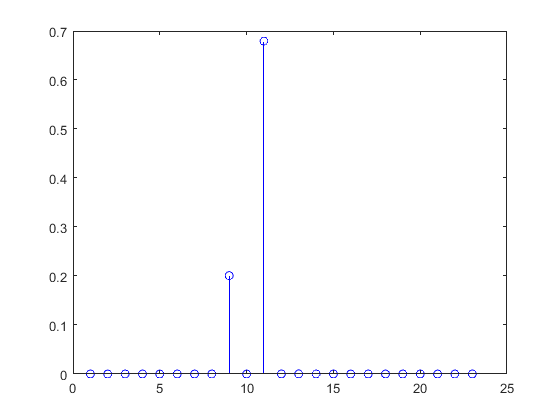

%here we find best features by matlab
runNCA = false;   % control whether to see NCA running or just load the selected features
    
if ~runNCA && isfile('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
    disp('SelectedFeatures.mat loaded')
    stem(mdl.FeatureWeights,'bo');
else % Perform feature selection with neighborhood component analysis
    rng(1);
    
    % first, let's make sure we've split the data (in case we skipped the
    % programmatic model training sections above)
    if ~exist('training_set')
        [training_set, test_set] = splitDataSets(feature_table,0.2);
    end
    
    mdl = fscnca(table2array(training_set(:,1:23)), table2array(training_set(:,24)), 'Lambda', 0.0005, 'Verbose', 0);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    % save for future reference
    save('SelectedFeatures.mat', 'selected_feature_indx');
end


% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

    'sampleKurtosis'    'MFCC1'



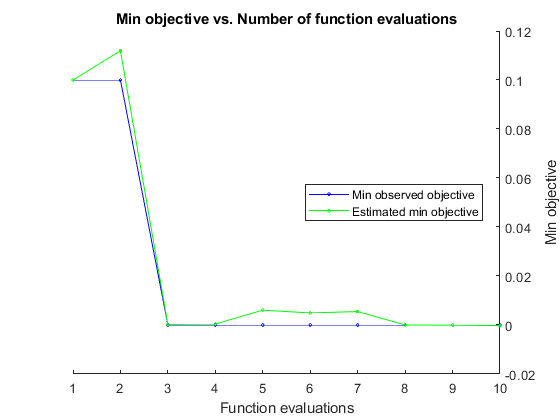

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |
|====================================================================================================================|
|    1 | Best   |         0.1 |      93.991 |         0.1 |         0.1 |          Bag |          421 |            - |
|    2 | Accept |         0.4 |       1.288 |         0.1 |     0.11193 |     RUSBoost |          277 |    0.0028086 |
|    3 | Best   |           0 |      3.0835 |           0 |  0.00024013 |  GentleBoost |           13 |    0.0099514 |
|    4 | Accept |         0.5 |     0.85472 |           0 |  0.00038357 |     RUSBoost |           42 |      0.27696 |
|    5 | Accept |           0 |      98.658 |   

trained_model_featsel =   classreg.learning.classif.ClassificationEnsemble
                       PredictorNames: {'sampleKurtosis'  'MFCC1'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'breath'  'cough'}
                       ScoreTransform: 'none'
                      NumObservations: 40
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 481
                               Method: 'GentleBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [481×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, <a href="ma

%here we train with features that we find in last part
trainReducedModel = false;    % control whether to re-train this model or load it from a previous run
subsample = 1:height(training_set);
if trainReducedModel | ~isfile('TrainedWaveletModel_FeatSel.mat')%#ok
    % configure key parameters: cross validation, cost, and hyperparameter
    % tuning
    rng(1)
    cvp = cvpartition(length(subsample),'KFold',5);
    C = [0, 10; 1, 0];            % Assign higher cost for misclassification of abnormal heart sounds
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',10);    
    
    % now we are ready to train...
    trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
    % save the model for later reference
    save('TrainedWaveletModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedWaveletModel_FeatSel.mat')
    disp(trained_model_featsel)
    disp('TrainedWaveletModel_FeatSel.mat loaded')
end


% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, test_set(:,selected_feature_indx));

conf_mat_featsel = confusionmat(test_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'cough', 'breath'};

% Visualize model performance
% probably custom AE version: heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);
heatmap(labels,labels,conf_mat_per_featsel, 'Colormap', winter, 'ColorbarVisible','off');